# Face detection

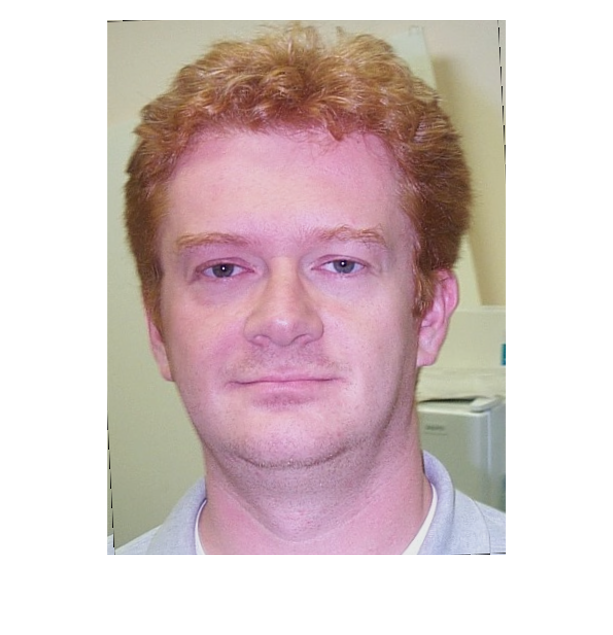

% 322 faces total

% Assume inputImage is the image you want to recognize
% inputImage = imread('images/DB0/db0_2.jpg');
inputImage = imread('images/DB1/db1_02.jpg');
% inputImage = imread('images/DB2/ex_01.jpg');
% inputImage = imread('images/all_img/image_0242.jpg');



inputImage = degrade_img(inputImage);
% inputImage = tone_compensation(inputImage);

imshow(inputImage);

% inputImage is the image to be classified 

id = tnm034(inputImage, 'fisherface');
disp(id)

## Accuracy DB1 and DB2

% Assuming you have a folder path

     2



folderPath = 'images/DB1';
imageFiles = dir(fullfile(folderPath, '*.jpg')); % Get all .jpg files in the folder

% Initialize counters
correctPredictions = 0;
totalImages = length(imageFiles);

% Loop through each image file
for i = 1:totalImages
    i

    % Extract the image number (label) from the filename
    [~, fileName, ~] = fileparts(imageFiles(i).name);
    % actualLabel = str2double(regexp(fileName, '\d+', 'match'));
    actualLabel = str2double(regexp(fileName, '\d+$', 'match'));

    % Read the image
    inputImage = imread(fullfile(folderPath, imageFiles(i).name));

    inputImage = degrade_img(inputImage);
    % inputImage = tone_compensation(inputImage);

    % Apply your function to get the predicted label
    predictedLabelString = tnm034(inputImage, 'fisherface');

    % Compare predicted label to actual label
    if predictedLabelString == actualLabel
        correctPredictions = correctPredictions + 1;
    else
        fprintf('Mismatch: File %s predicted as %d but actual is %d\n', ...
            imageFiles(i).name, predictedLabelString, actualLabel);
    end
end

% Calculate the total accuracy
accuracy = correctPredictions / totalImages * 100;
fprintf('The total accuracy is %.2f%%\n', accuracy);

i = 1

i = 2

Mismatch: File db1_02.jpg predicted as 10 but actual is 2


i = 3

i = 4

i = 5

i = 6

Mismatch: File db1_06.jpg predicted as 13 but actual is 6


i = 7

i = 8

i = 9

Mismatch: File db1_09.jpg predicted as 13 but actual is 9


i = 10

Mismatch: File db1_10.jpg predicted as 4 but actual is 10


i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

## Accuracy DB3

% Assuming you have a top-level folder path
folderPath = 'images/DB3'; % Replace with your actual top-level folder path
subFolders = dir(folderPath);

The total accuracy is 75.00%


subFolders = subFolders([subFolders.isdir]); % Filter out non-directory files
subFolders = subFolders(~ismember({subFolders.name}, {'.', '..'})); % Remove '.' and '..'

% Initialize counters
correctPredictions = 0;
totalImages = 0;

% Loop through each subfolder
for i = 1:length(subFolders)
    subFolderPath = fullfile(folderPath, subFolders(i).name);
    imageFiles = dir(fullfile(subFolderPath, '*.jpg')); % Get all .jpg files in the subfolder
    
    % Loop through each image file in the subfolder
    for j = 1:length(imageFiles)
        
        j

        % Read the image
        inputImage = imread(fullfile(subFolderPath, imageFiles(j).name));

        inputImage = degrade_img(inputImage);
        inputImage = tone_compensation(inputImage);

        % Apply your function to get the predicted label as string
        predictedLabelString = tnm034(inputImage, 'fisherface');
        
        % Increment total images count
        totalImages = totalImages + 1;

        % The actual label is the name of the subfolder
        actualLabelString = subFolders(i).name;
        
        % Extract the numeric part of the subfolder name
        actualLabel = str2double(regexp(actualLabelString, '\d+', 'match'));
        
        % Validate that the conversion was successful
        if isnan(predictedLabelString)
            error('Predicted label conversion to double failed for file: %s', imageFiles(j).name);
        end

        % Compare predicted label to actual label
        if predictedLabelString == actualLabel
            correctPredictions = correctPredictions + 1;
        else
            fprintf('Mismatch: File %s predicted as %d but actual is %d\n', ...
                imageFiles(j).name, predictedLabelString, actualLabel);
        end
    end
end

% Calculate the total accuracy
accuracy = correctPredictions / totalImages * 100;
fprintf('The total accuracy is %.2f%%\n', accuracy);

j = 1

j = 2

j = 3

j = 4

j = 5

j = 6

j = 7

j = 8

j = 9

Mismatch: File image_0008.jpg predicted as 4 but actual is 1


j = 10

j = 11

Mismatch: File image_0010.jpg predicted as 2 but actual is 1


j = 12

j = 13

j = 14

j = 15

j = 16

No face detected.


Mismatch: File image_0015.jpg predicted as 0 but actual is 1


j = 17

No face detected.


Mismatch: File image_0016.jpg predicted as 0 but actual is 1


j = 18

j = 19

j = 20

j = 21

j = 22

j = 1

j = 2

Mismatch: File image_0242.jpg predicted as 14 but actual is 10


j = 3

j = 4

No face detected.


Mismatch: File image_0244.jpg predicted as 0 but actual is 10


j = 5

j = 6

j = 7

j = 8

j = 9

No face detected.


Mismatch: File image_0249.jpg predicted as 0 but actual is 10


j = 10

No face detected.


Mismatch: File image_0250.jpg predicted as 0 but actual is 10


j = 11

j = 12

Mismatch: File image_0252.jpg predicted as 8 but actual is 10


j = 13

Mismatch: File image_0253.jpg predicted as 8 but actual is 10


j = 14

j = 15

j = 16

j = 17

No face detected.


Mismatch: File image_0257.jpg predicted as 0 but actual is 10


j = 18

j = 19

No face detected.


Mismatch: File image_0259.jpg predicted as 0 but actual is 10


j = 20

j = 21

j = 22

j = 23

j = 1

j = 2

j = 3

Mismatch: File image_0270.jpg predicted as 13 but actual is 11


j = 4

j = 5

j = 6

j = 7

j = 8

j = 9

j = 10

j = 11

j = 12

j = 13

Mismatch: File image_0280.jpg predicted as 1 but actual is 11


j = 14

j = 15

j = 16

j = 17

j = 18

j = 19

j = 20

j = 1

j = 2

j = 3

j = 4

j = 5

j = 6

j = 7

j = 8

j = 9

j = 10

Mismatch: File image_0345.jpg predicted as 3 but actual is 12


j = 11

j = 12

j = 13

j = 14

Mismatch: File image_0349.jpg predicted as 10 but actual is 12


j = 15

j = 16

j = 17

j = 18

j = 19

j = 20

j = 21

j = 1

j = 2

j = 3

j = 4

j = 5

Mismatch: File image_0360.jpg predicted as 1 but actual is 13


j = 6

j = 7

j = 8

j = 9

j = 10

j = 11

Mismatch: File image_0366.jpg predicted as 7 but actual is 13


j = 12

j = 13

j = 14

j = 15

j = 16

j = 17

j = 18

Mismatch: File image_0373.jpg predicted as 1 but actual is 13


j = 19

j = 20

Mismatch: File image_0375.jpg predicted as 1 but actual is 13


j = 21

j = 1

j = 2

j = 3

Mismatch: File image_0378.jpg predicted as 4 but actual is 14


j = 4

j = 5

j = 6

Mismatch: File image_0381.jpg predicted as 1 but actual is 14


j = 7

j = 8

j = 9

Mismatch: File image_0384.jpg predicted as 4 but actual is 14


j = 10

j = 11

j = 12

j = 13

Mismatch: File image_0388.jpg predicted as 1 but actual is 14


j = 14

j = 15

j = 16

j = 17

j = 18

j = 19

j = 20

j = 21

Mismatch: File image_0396.jpg predicted as 7 but actual is 14


j = 22

Mismatch: File image_0397.jpg predicted as 13 but actual is 14


j = 23

j = 1

j = 2

j = 3

j = 4

j = 5

j = 6

j = 1

j = 2

j = 3

j = 4

j = 5

j = 6

j = 7

j = 8

j = 9

j = 10

j = 11

j = 12

j = 13

j = 14

j = 15

j = 16

j = 17

j = 18

Mismatch: File image_0425.jpg predicted as 4 but actual is 16


j = 19

j = 20

j = 21

j = 1

j = 2

j = 3

j = 4

j = 5

Mismatch: File image_0025.jpg predicted as 12 but actual is 2


j = 6

Mismatch: File image_0026.jpg predicted as 10 but actual is 2


j = 7

j = 8

No eyes detected within the face region.


Mismatch: File image_0028.jpg predicted as 0 but actual is 2


j = 9

j = 10

Mismatch: File image_0030.jpg predicted as 10 but actual is 2


j = 11

j = 12

j = 13

j = 14

j = 15

j = 16

Mismatch: File image_0036.jpg predicted as 4 but actual is 2


j = 17

j = 18

j = 19

j = 20

j = 21

Mismatch: File image_0041.jpg predicted as 12 but actual is 2


j = 1

j = 2

j = 3

Mismatch: File image_0048.jpg predicted as 1 but actual is 3


j = 4

j = 5

j = 6

j = 7

j = 8

j = 9

j = 10

j = 11

j = 12

j = 13

Mismatch: File image_0058.jpg predicted as 13 but actual is 3


j = 14

j = 15

j = 16

j = 17

Mismatch: File image_0062.jpg predicted as 13 but actual is 3


j = 18

j = 19

j = 20

j = 21

j = 22

Mismatch: File image_0067.jpg predicted as 13 but actual is 3


j = 23

j = 1

j = 2

j = 3

j = 4

j = 5

Mismatch: File image_0093.jpg predicted as 6 but actual is 4


j = 6

j = 7

Mismatch: File image_0095.jpg predicted as 13 but actual is 4


j = 8

j = 9

j = 10

Mismatch: File image_0098.jpg predicted as 1 but actual is 4


j = 11

Mismatch: File image_0099.jpg predicted as 1 but actual is 4


j = 12

j = 13

j = 14

j = 15

j = 16

j = 17

j = 18

Mismatch: File image_0106.jpg predicted as 1 but actual is 4


j = 19

j = 20

j = 21

j = 22

j = 23

j = 24

j = 1

j = 2

j = 3

Mismatch: File image_0134.jpg predicted as 4 but actual is 5


j = 4

No face detected.


Mismatch: File image_0135.jpg predicted as 0 but actual is 5


j = 5

Mismatch: File image_0136.jpg predicted as 3 but actual is 5


j = 6

Mismatch: File image_0137.jpg predicted as 13 but actual is 5


j = 1

j = 2

j = 3

Mismatch: File image_0139.jpg predicted as 4 but actual is 6


j = 4

j = 5

j = 6

Mismatch: File image_0142.jpg predicted as 13 but actual is 6


j = 7

j = 8

j = 9

j = 10

Mismatch: File image_0146.jpg predicted as 4 but actual is 6


j = 11

j = 12

j = 13

j = 14

Mismatch: File image_0150.jpg predicted as 13 but actual is 6


j = 15

j = 16

Mismatch: File image_0152.jpg predicted as 5 but actual is 6


j = 17

Mismatch: File image_0153.jpg predicted as 4 but actual is 6


j = 18

j = 19

j = 20

j = 21

j = 22

j = 1

No face detected.


Mismatch: File db1_07.jpg predicted as 0 but actual is 7


j = 2

j = 3

j = 4

j = 5

Mismatch: File image_0179.jpg predicted as 1 but actual is 7


j = 6

j = 7

j = 8

No face detected.


Mismatch: File image_0182.jpg predicted as 0 but actual is 7


j = 9

j = 10

j = 11

Mismatch: File image_0185.jpg predicted as 13 but actual is 7


j = 12

j = 13

j = 14

j = 15

j = 16

Mismatch: File image_0190.jpg predicted as 6 but actual is 7


j = 17

No eyes detected within the face region.


Mismatch: File image_0191.jpg predicted as 0 but actual is 7


j = 18

Mismatch: File image_0192.jpg predicted as 1 but actual is 7


j = 19

No face detected.


Mismatch: File image_0193.jpg predicted as 0 but actual is 7


j = 20

j = 21

No face detected.


Mismatch: File image_0195.jpg predicted as 0 but actual is 7


j = 1

Mismatch: File db1_08.jpg predicted as 16 but actual is 8


j = 2

Mismatch: File image_0196.jpg predicted as 6 but actual is 8


j = 3

j = 4

j = 5

j = 6

Mismatch: File image_0200.jpg predicted as 13 but actual is 8


j = 7

j = 8

j = 9

j = 10

j = 11

j = 12

j = 13

j = 14

j = 15

j = 16

Mismatch: File image_0210.jpg predicted as 3 but actual is 8


j = 17

j = 18

Mismatch: File image_0212.jpg predicted as 4 but actual is 8


j = 19

j = 20

j = 21

Mismatch: File image_0215.jpg predicted as 4 but actual is 8


j = 22

j = 1

Mismatch: File db1_09.jpg predicted as 13 but actual is 9


j = 2

Mismatch: File image_0217.jpg predicted as 13 but actual is 9


j = 3

j = 4

j = 5

j = 6

j = 7

j = 8

j = 9

j = 10

Mismatch: File image_0225.jpg predicted as 1 but actual is 9


j = 11

j = 12

j = 13

j = 14

j = 15

j = 16

j = 17

Mismatch: File image_0232.jpg predicted as 1 but actual is 9


j = 18

j = 19

Mismatch: File image_0234.jpg predicted as 14 but actual is 9


j = 20

j = 21

j = 22

j = 23

j = 24

j = 25

No eyes detected within the face region.


Mismatch: File image_0240.jpg predicted as 0 but actual is 9


j = 26

Mismatch: File image_0241.jpg predicted as 6 but actual is 9


The total accuracy is 77.02%
